score = [2.0 4.8 9.5 10;
         3.3 5.2 9.9 10;
         1.0 3.3 10.0 10;
         4.3 4.0 9.1 10;
         1.5 7.8 10.0 10;
         2.9 6.6 9.7 10;
         1.0 5.5 8.9 10;
         2.8 8.9 8.5 10;
         0.0 2.0 9.2 10;
         3.5 8.1 9.9 10];

score_static = [5 8 10;
                5 9 9;
                7 9 10;
                4 8 10;
                6 8 9;
                5 9 9;
                5 9 8;
                6 8 9;];
t = linspace(0,20,200);

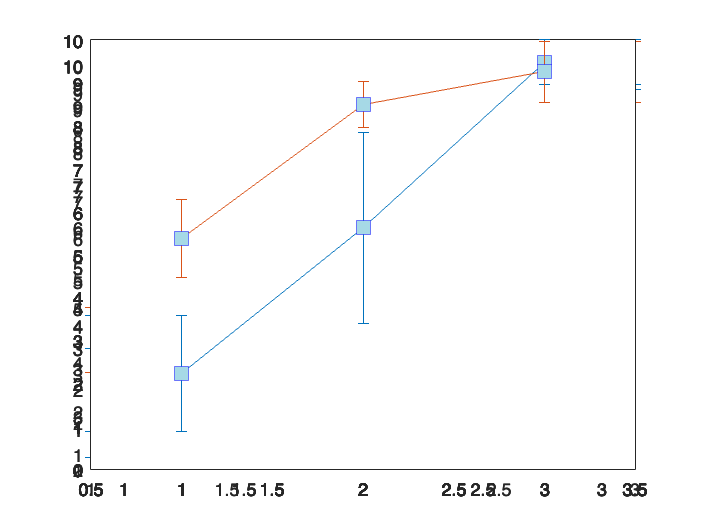

 
ax = axes;
spacing = [1 2 3];
mean_move = mean(score(:,1:3));
std_move = std(score(:,1:3));

errorbar(ax, spacing, mean_move, std_move,"-s","MarkerSize",10,...
    "MarkerEdgeColor","blue","MarkerFaceColor",[0.65 0.85 0.90])
% axis(ax,"padded")
hold(ax,"on")

mean_static = mean(score_static);
std_static = std(score_static);
errorbar(ax, spacing, mean_static, std_static,"-s","MarkerSize",10,...
    "MarkerEdgeColor","blue","MarkerFaceColor",[0.65 0.85 0.90])

ax.XLim = [0.5 3.5];
ax.XTick = [];
ax.YTick = [];
hold(ax,"off")

 
for i = 1:1:4
b = bar(score(:,5-i));
hold on
end
maxline = yline(10,'--');

title( 'Match Scores for 3 labeling algorithm','FontSize',12)
xlabel("Trail ID")
ylabel("Match Score")
txt = '\leftarrow sin(\pi) = 0';
text(10,10.4,'Total Number of Markers','FontSize',12,'BackgroundColor',[1,1,1])
ylim([0 12])
box off
colormap(summer)

% lgd = legend(b,{'Raw Data', 'Naive Labeling', 'PSA Labeling'},'Location','north', 'Orientation','horizontal');
lgd.Box = "off";

fontsize(gca,20,'points')

% set(gcf,'Position',[100 100 1000 500])

 
bxp = boxplot(score,...
    'Widths',0.6,...
    'Labels',{'Raw Data', 'Naive Labeling', 'Proposed Labeling'},...
    'Whisker',1, ...
    'OutlierSize',20);
title('Match Scores for 3 Labeling Algorithm')
set(gcf,'Position',[100 100 400 300])


mean(score,1)

 
f1 = figure;
ax1 = axes;

plot(ax1,t,x,'LineWidth',1,'Marker','o','MarkerSize',5, ...
    'Color',[0.993248, 0.906157, 0.143936])
hold on
plot(ax1,t,label_x,...
    'Marker','*', ...
    'MarkerSize',7, ...
    'Color',[0.146389, 0.433597, 0.709876])
plot(ax1,t,naive_x,'Marker','diamond','MarkerSize',7, ...
    'Color',[0.267004, 0.004874, 0.329415])
ax1.XLim = [0,20];
ax1.YLim = [-50,220];
legend(ax1,{'Ground Truth', 'Proposed Labeling Method', 'Naive Labeling Method'})
figure(f1)

    

 
f2 = figure;
ax2 = axes;
figure(f2)
y =  0.1* (0.002 * t.^4 - 0.05* t.^3 - log(t).* t.^2 - t ) .* (cos(t/8))+ 10 + 20*(rand(1,size(t,2))-0.5);
label_y = 0.1* (0.002 * t.^4 - 0.05* t.^3 - log(t).* t.^2 - t ) .* (cos(t/8))+ 10 + 20*(rand(1,size(t,2))-0.5);
naive_y = label_y;

idx = [ 10,14, 58,133,150,198];
label_y(idx) = label_y(idx)+100*(rand(1,size(idx,2)) - 0.5);


idx = [1:28, 70:101, 142:149, 177:195];
naive_y(idx) = naive_y(idx)+400*(rand(1,size(idx,2)) - 0.5);
plot(ax2,t,y,'LineWidth',1,'Marker','o','MarkerSize',5, ...
    'Color',[0.993248, 0.906157, 0.143936])
hold on

plot(ax2,t,label_y, ...
     'Marker','*', ...
    'MarkerSize',7, ...
    'Color',[0.146389, 0.433597, 0.709876])
plot(ax2,t,naive_y, ...
    'Marker','diamond','MarkerSize',7, ...
    'Color',[0.267004, 0.004874, 0.329415])
legend(ax2,{'Ground Truth', 'Proposed Labeling Method', 'Naive Labeling Method'})

 
f3 = figure;
ax3 = axes;
figure(f3)
z = 0.1*( -0.003646*t.^5 +  0.159 *t.^4 + -2.421*t.^3 + 14.89 *t.^2 + -24.99*x +  -201.9) + 20*(rand(1,size(t,2))-0.5);
label_z = 0.1*( -0.003646*t.^5 +  0.159 *t.^4 + -2.421*t.^3 + 14.89 *t.^2 + -24.99*x +  -201.9) + 20*(rand(1,size(t,2))-0.5);
naive_z = label_z;

idx = [ 10,14, 58,133,150,198];
label_z(idx) = label_z(idx)+50*(rand(1,size(idx,2)) - 0.5);

idx = [1:28, 70:101, 142:149, 177:195];
naive_z(idx) = naive_z(idx)+1000*(rand(1,size(idx,2)) - 0.5);
plot(ax3,t,z,'LineWidth',1,'Marker','o','MarkerSize',5, ...
    'Color',[0.993248, 0.906157, 0.143936])
hold on
plot(ax3,t,label_z, ...
     'Marker','*', ...
    'MarkerSize',7, ...
    'Color',[0.146389, 0.433597, 0.709876])
plot(ax3,t,naive_z, ...
    'Marker','diamond','MarkerSize',7, ...
    'Color',[0.267004, 0.004874, 0.329415])
legend(ax3,{'Ground Truth', 'Proposed Labeling Method', 'Naive Labeling Method'})

 
f4 = figure;
figure(f4)
f4.Position = [100 100 1200 400]
ax_x = subplot(1,3,1);
ax_y = subplot(1,3,2);
ax_z = subplot(1,3,3);
hold(ax_x)
hold(ax_y)
hold(ax_z)
title(ax_x,'X Coordinate')
title(ax_y,'Y Coordinate')
title(ax_z,'Z Coordinate')
sgtitle('Recorded Poition for Marker # 8');
xlabel(ax_x,'time t/s')
xlabel(ax_y,'time t/s')
xlabel(ax_z,'time t/s')
ylabel(ax_x,'x coordinate /mm')
ylabel(ax_y,'y coordinate /mm')
ylabel(ax_z,'z coordinate /mm')

% prepare the data
t = 0:0.1:20;
x = 10*(20 * sin(t/5)+ 12* cos(t/3).*sin(t/10) + exp(t/20) + 5* cos(t/2).*cos(t/20)) + 10*(rand(1,size(t,2))-0.5);
y =  0.1* (0.002 * t.^4 - 0.05* t.^3 - log(t).* t.^2 - t ) .* (cos(t/8))+ 10 + 20*(rand(1,size(t,2))-0.5);
z = 0.1*( -0.003646*t.^5 +  0.159 *t.^4 + -2.421*t.^3 + 14.89 *t.^2 + -24.99*x +  -201.9) + 20*(rand(1,size(t,2))-0.5);

% make labeling and naive method data
label_x = 10*(20 * sin(t/5)+ 12* cos(t/3).*sin(t/10) + exp(t/20) + 5* cos(t/2).*cos(t/20)) + 20*(rand(1,size(t,2))-0.5);
naive_x = label_x;
label_y = 0.1* (0.002 * t.^4 - 0.05* t.^3 - log(t).* t.^2 - t ) .* (cos(t/8))+ 10 + 20*(rand(1,size(t,2))-0.5);
naive_y = label_y;
label_z = 0.1*( -0.003646*t.^5 +  0.159 *t.^4 + -2.421*t.^3 + 14.89 *t.^2 + -24.99*x +  -201.9) + 20*(rand(1,size(t,2))-0.5);
naive_z = label_z;


idx = [ 10,14, 58,133,150,198];
label_x(idx) = label_x(idx)+100*(rand(1,size(idx,2)) - 0.5);
label_y(idx) = label_y(idx)+100*(rand(1,size(idx,2)) - 0.5);
label_z(idx) = label_z(idx)+50*(rand(1,size(idx,2)) - 0.5);

idx = [1:28, 70:101, 142:149, 177:195];
naive_x(idx) = naive_x(idx)+250*(rand(1,size(idx,2)) - 0.5);
naive_y(idx) = naive_y(idx)+400*(rand(1,size(idx,2)) - 0.5);
naive_z(idx) = naive_z(idx)+1000*(rand(1,size(idx,2)) - 0.5);

% plot x component   
plot(ax_x,t,x,'LineWidth',1,'Marker','o','MarkerSize',5, ...
    'Color',[0.993248, 0.906157, 0.143936])

plot(ax_x,t,label_x, ...
     'Marker','*', ...
    'MarkerSize',7, ...
    'Color',[0.146389, 0.433597, 0.709876])
plot(ax_x,t,naive_x, ...
    'Marker','diamond','MarkerSize',7, ...
    'Color',[0.267004, 0.004874, 0.329415])
legend(ax_x,{'Ground Truth', 'Proposed Labeling Method', 'Naive Labeling Method'})

% y component
plot(ax_y,t,y,'LineWidth',1,'Marker','o','MarkerSize',5, ...
    'Color',[0.993248, 0.906157, 0.143936])
plot(ax_y,t,label_y, ...
     'Marker','*', ...
    'MarkerSize',7, ...
    'Color',[0.146389, 0.433597, 0.709876])
plot(ax_y,t,naive_y, ...
    'Marker','diamond','MarkerSize',7, ...
    'Color',[0.267004, 0.004874, 0.329415])
legend(ax_y,{'Ground Truth', 'Proposed Labeling Method', 'Naive Labeling Method'})

% z component
plot(ax_z,t,z,'LineWidth',1,'Marker','o','MarkerSize',5, ...
    'Color',[0.993248, 0.906157, 0.143936])
plot(ax_z,t,label_z, ...
     'Marker','*', ...
    'MarkerSize',7, ...
    'Color',[0.146389, 0.433597, 0.709876])
plot(ax_z,t,naive_z, ...
    'Marker','diamond','MarkerSize',7, ...
    'Color',[0.267004, 0.004874, 0.329415])
legend(ax_z,{'Ground Truth', 'Proposed Labeling Method', 'Naive Labeling Method'})


 
base_x = 0.00002 * t.^8 + 0.00074 * t.^7 - 0.01617*t.^6 + 0.21206*t.^5 - 1.71087*t.^4 + 8.4202*t.^3 - 23.71846*t.^2 + 30.80166*t - 2.45359;
x = base_x + 20*(rand(1,size(t,2))-0.5);
figure
plot(t,base_x)
label_x = 10*(20 * sin(t/5)+ 12* cos(t/3).*sin(t/10) + exp(t/20) + 5* cos(t/2).*cos(t/20)) + 20*(rand(1,size(t,2))-0.5);
naive_x = label_x;

idx = [ 10,14, 58,133,150,198];
label_x(idx) = label_x(idx)+100*(rand(1,size(idx,2)) - 0.5);

 
f2 = figure();
figure(f2)
f2.Position = [0 0 500 800];

ax_g = subplot(6,2,[1,2]);
ax_p = subplot(6,2,3);
ax_n = subplot(6,2,4);
ay_g = subplot(6,2,[5,6]);
ay_p = subplot(6,2,7);
ay_n = subplot(6,2,8);
az_g = subplot(6,2,[9,10]);
az_p = subplot(6,2,11);
az_n = subplot(6,2,12);



x = 10*(20 * sin(t/5)+ 12* cos(t/3).*sin(t/10) + exp(t/20) + 5* cos(t/2).*cos(t/20)) + 10*(rand(1,size(t,2))-0.5);
label_x = 10*(20 * sin(t/5)+ 12* cos(t/3).*sin(t/10) + exp(t/20) + 5* cos(t/2).*cos(t/20)) + 20*(rand(1,size(t,2))-0.5);
naive_x = label_x;

y =  -300*ones([1,200]) + 0.1* (0.002 * t.^4 - 0.05* t.^3 - log(t).* t.^2 - t ) .* (cos(t/8))+ 10 + 20*(rand(1,size(t,2))-0.5);
label_y = -300*ones([1,200]) + 0.1* (0.002 * t.^4 - 0.05* t.^3 - log(t).* t.^2 - t ) .* (cos(t/8))+ 10 + 20*(rand(1,size(t,2))-0.5);
naive_y = label_y;

z = 0.1*( -0.003646*t.^5 +  0.159 *t.^4 + -2.421*t.^3 + 14.89 *t.^2 + -24.99*x +  -201.9) + 20*(rand(1,size(t,2))-0.5);
label_z = 0.1*( -0.003646*t.^5 +  0.159 *t.^4 + -2.421*t.^3 + 14.89 *t.^2 + -24.99*x +  -201.9) + 20*(rand(1,size(t,2))-0.5);
naive_z = label_z;

idx = [ 10,14, 58,133,150,198];
label_x(idx) = label_x(idx)+100*(rand(1,size(idx,2)) - 0.5);
label_y(idx) = label_y(idx)+100*(rand(1,size(idx,2)) - 0.5);
label_z(idx) = label_z(idx)+50*(rand(1,size(idx,2)) - 0.5);

idx = [1:28, 70:101, 142:149, 177:195];
naive_x(idx) = naive_x(idx)+250*(rand(1,size(idx,2)) - 0.5);
naive_y(idx) = naive_y(idx)+400*(rand(1,size(idx,2)) - 0.5);
naive_z(idx) = naive_z(idx)+1000*(rand(1,size(idx,2)) - 0.5);

plot(ax_g,t,x,'LineWidth',1,...
    'MarkerSize',5, ...
    'Color',[0.993248, 0.906157, 0.143936])
plot(ax_p,t,label_x-x, ...
    'MarkerSize',7, ...
    'Color',[0.146389, 0.433597, 0.709876])
plot(ax_n,t,naive_x-x, ...
    'MarkerSize',7, ...
    'Color',[0.267004, 0.004874, 0.329415])

plot(ay_g,t,y,'LineWidth',1,...
    'MarkerSize',5, ...
    'Color',[0.993248, 0.906157, 0.143936])
plot(ay_p,t,label_y-y, ...
    'MarkerSize',7, ...
    'Color',[0.146389, 0.433597, 0.709876])
plot(ay_n,t,naive_y-y, ...
    'MarkerSize',7, ...
    'Color',[0.267004, 0.004874, 0.329415])

plot(az_g,t,z,'LineWidth',1,...
    'MarkerSize',5, ...
    'Color',[0.993248, 0.906157, 0.143936])
hold on
plot(az_p,t,label_z-z, ...
    'MarkerSize',7, ...
    'Color',[0.146389, 0.433597, 0.709876])
plot(az_n,t,naive_z-z, ...
    'MarkerSize',7, ...
    'Color',[0.267004, 0.004874, 0.329415])

title(ax_g,'Motion of Marker 8 in X Direction')
title(ax_p,'PSA Labeling Error')
title(ax_n,'Naive Labeling Error')
legend(ax_g,{'Ground Truth'})
legend(ax_p,{'PSA Labeling'})
legend(ax_n,{'Naive Labeling'})
grid(ax_g,"on")
grid(ax_p,"on")
grid(ax_n,"on")
ylim(ax_g,[-100,200]);
ylim(ax_p,[-200,200]);
ylim(ax_n,[-200,200]);
xlabel(ax_g,'time t/s')
xlabel(ax_p,'time t/s')
xlabel(ax_n,'time t/s')
ylabel(ax_g,'x/mm')
ylabel(ax_p,'x/mm')
ylabel(ax_n,'x/mm')

title(ay_g,'Motion of Marker 8 in Y Direction')
title(ay_p,'PSA Labeling Error')
title(ay_n,'Naive Labeling Error')
legend(ay_g,{'Ground Truth'})
legend(ay_p,{'PSA Labeling'})
legend(ay_n,{'Naive Labeling'})
grid(ay_g,"on")
grid(ay_p,"on")
grid(ay_n,"on")
ylim(ay_g,[-350,-100]);
ylim(ay_p,[-200,200]);
ylim(ay_n,[-200,200]);
xlabel(ay_g,'time t/s')
xlabel(ay_p,'time t/s')
xlabel(ay_n,'time t/s')
ylabel(ay_g,'y/mm')
ylabel(ay_p,'y/mm')
ylabel(ay_n,'y/mm')

title(az_g,'Motion of Marker 8 in Z Direction')
title(az_p,'PSA Labeling Error')
title(az_n,'Naive Labeling Error')
legend(az_g,{'Ground Truth'})
legend(az_p,{'PSA Labeling'})
legend(az_n,{'Naive Labeling'})
grid(az_g,"on")
grid(az_p,"on")
grid(az_n,"on")
ylim(az_g,[-450,200]);
ylim(az_p,[-200,200]);
ylim(az_n,[-300,300]);
xlabel(az_g,'time t/s')
xlabel(az_p,'time t/s')
xlabel(az_n,'time t/s')
ylabel(az_g,'z/mm')
ylabel(az_p,'z/mm')
ylabel(az_n,'z/mm')
ylim(az_n,[-300,300]);


box on